**1. Create test data**

maxPWM = 1.00;  % maximum duty cycle
incrPWM = 0.05;  % PWM increment
PWMcmdRaw = (-maxPWM:incrPWM:maxPWM)';  % column vector of duty cycles from -1 to 1

**2. Create and initialize device objects**

clear a dcm carrier enc  % delete existing device objects
a = arduino;
carrier = addon(a,'Arduino/MKRMotorCarrier');
dcm = dcmotor(carrier,3);
enc = rotaryEncoder(carrier,1);
resetCount(enc);

**3-5. Call motor characterization function**

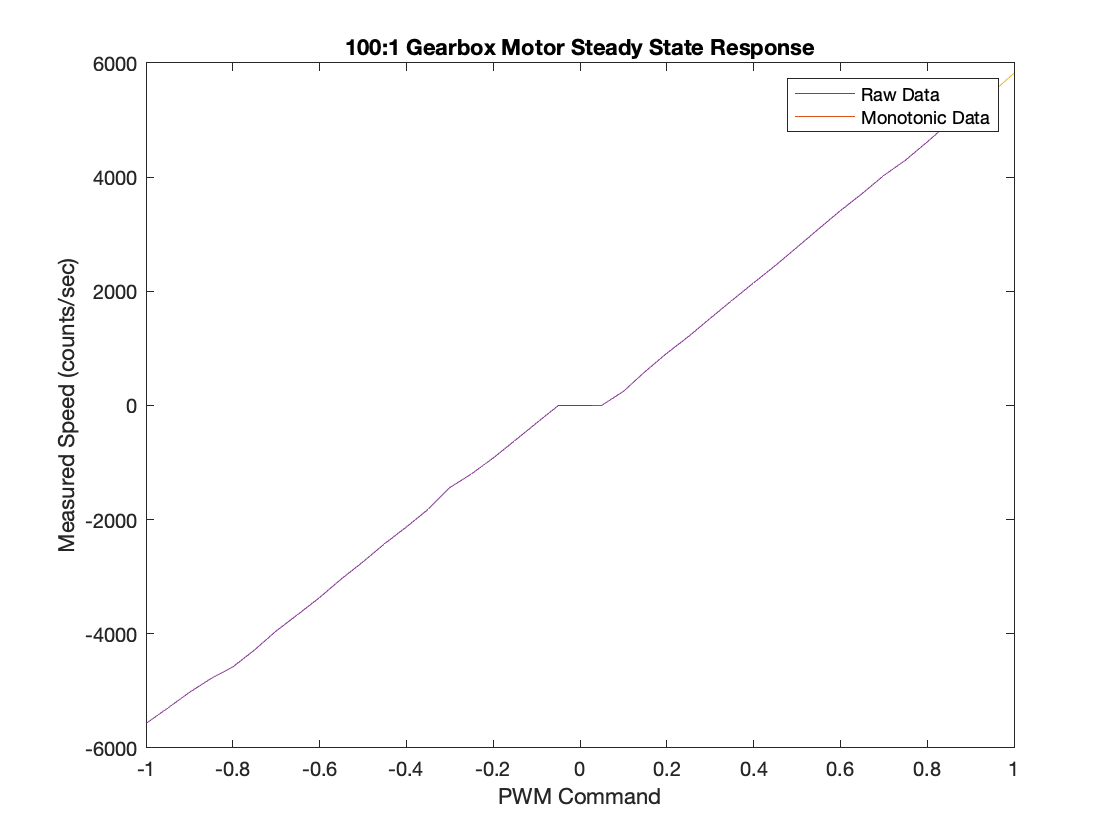

[PWMcmdMono,speedMono] = myMotorFunction(PWMcmdRaw,dcm,enc,'motorResponse');

**6. Delete device objects**

clear a dcm carrier enc